% gpuDeviceCount("available")
% gpuDeviceTable

out

out =   Simulink.SimulationOutput:

                   cost: [1x1 timeseries] 
             laneVector: [1x1 timeseries] 
                  lanes: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                     mv: [1x1 timeseries] 
             mv_command: [1x1 timeseries] 
                mv_real: [1x1 timeseries] 
                 mv_seq: [1x1 timeseries] 
             solverStat: [1x1 timeseries] 
                  state: [1x1 struct] 
                 status: [1x1 timeseries] 
                   tout: [101x1 double] 
              waypoints: [1x1 timeseries] 
     waypoints_relative: [1x1 timeseries] 
                  x_seq: [1x1 timeseries] 
                  y_seq: [1x1 timeseries] 
                yawRate: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


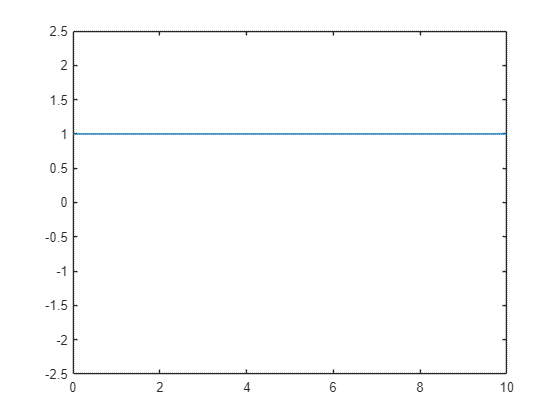


figure
plot(out.solverStat.Time, out.solverStat.Data)
axis([T0 Te -2.5 2.5])

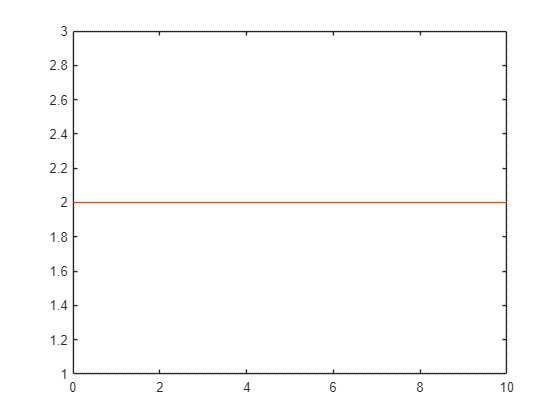


i=1;
% 
% 
% mv_real=out.mv_real.Data;
% t_mv_real=out.mv_real.Time;
% mv_command=out.mv_command.Data;
% t_mv_command=out.mv_command.Time;
% 
% figure
% plot(t_mv_command,mv_command(:,1))
% hold on
% plot(t_mv_real,mv_real(:,1))
% grid on
% legend('acc_command','acc_real')
% 
% figure
% plot(t_mv_command,mv_command(:,2))
% hold on
% plot(t_mv_real,mv_real(:,2))
% grid on
% legend('steer_command','steer_real')
% v=out.state.Velocity.Data(1,1,:);
% v=reshape(v,[size(v,3),1]);
% t_v=out.state.Velocity.Time;
% figure
% plot(t_v,v)
% legend('speed')

t_lanes=out.lanes.Time.Data;
t_lanes=reshape(t_lanes,1,length(t_lanes));

% numLanes=out.lanes.NumLaneBoundaries.Data;
% numLanes=reshape(numLanes,1,length(numLanes));
% figure
% plot(t_lanes,numLanes)

laneType_l=out.lanes.LaneBoundaries(1).BoundaryType.Data;
laneType_l=reshape(laneType_l,1,length(laneType_l));
laneType_r=out.lanes.LaneBoundaries(2).BoundaryType.Data;
laneType_r=reshape(laneType_r,1,length(laneType_r));
figure
plot(t_lanes,laneType_l)
hold on
plot(t_lanes,laneType_r)


lane=out.lanes.LaneBoundaries(1)

lane = struct with fields:
              Curvature: [1×1 timeseries]
    CurvatureDerivative: [1×1 timeseries]
            CurveLength: [1×1 timeseries]
           HeadingAngle: [1×1 timeseries]
          LateralOffset: [1×1 timeseries]
           BoundaryType: [1×1 timeseries]
               Strength: [1×1 timeseries]
                  Width: [1×1 timeseries]


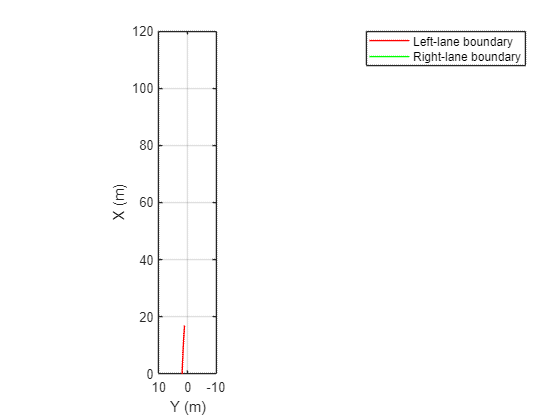


LB_l=clothoidLaneBoundary;
LB_l.Curvature=lane.Curvature.Data(:,:,i);
LB_l.CurvatureDerivative=lane.CurvatureDerivative.Data(:,:,i);
LB_l.CurveLength=lane.CurveLength.Data(:,:,i);
LB_l.HeadingAngle=lane.HeadingAngle.Data(:,:,i);
LB_l.LateralOffset=lane.LateralOffset.Data(:,:,i);
bep = birdsEyePlot('XLimits',[0 120],'YLimits',[-10 10]);
lbPlotter = laneBoundaryPlotter(bep,'DisplayName','Left-lane boundary','Color','r');
rbPlotter = laneBoundaryPlotter(bep,'DisplayName','Right-lane boundary','Color','g');
plotLaneBoundary(lbPlotter,LB_l)
grid
hold on

LB_vec=out.laneVector.Data(:,:,i)

LB_vec =    -0.0902   -0.0907
   -0.0007   -0.0006
   16.9219   16.8064
   -2.0045   -2.0109
    1.8807   -2.0820
    2.0000    2.0000


% x_sample=linspace(0,100,101);
% LB_l_y = coumputeBoundary(LB_l_vec(:,1), x_sample);
% plot(x_sample,LB_l_y,'b^')

state_pos=out.state.Position.Data(:,1:2,i);
state_vel=out.state.Velocity.Data(:,1:2,i);
state_yaw=out.state.Yaw.Data(:,:,i);

waypoint_bf=out.waypoints_relative.Data(1,:,i)

waypoint_bf =    -1.8610   -0.9460



mv_seq=out.mv_seq.Data(:,:,i)

mv_seq =     2.7346    0.0010
    2.4308    0.0009
    2.1270    0.0007
    1.8232    0.0005
    0.6512   -0.0018
    0.6512   -0.0018
    0.6512   -0.0018
    0.6512   -0.0018
    0.6512   -0.0018
    0.6512   -0.0018


action_i=out.mv.Data(i,:)

action_i =     2.7346    0.0010


% action_i=mv_seq(1,:)

state_i=[0,0,0,state_vel(1)]'

state_i =          0
         0
         0
   -0.0583



nextState_dynamics = vehicleDynamics_Simple(state_i, action_i, ...
    Ts, L, waypoints, ...
    cosFuncWeights.weights, EgoCar1_params.Limits.limits, ...
    2, LB_vec)

nextState_dynamics =    -0.0058
         0
   -0.0000
    0.2152


nextState_pose=out.state.Position.Data(:,1:2,i+1);
deltaState_pos=world2body(state_pos', state_yaw, nextState_pose')';
deltaState_yaw=out.state.Yaw.Data(:,:,i+1)-state_yaw;
newState_vel=out.state.Velocity.Data(:,1,i+1);
nextState_simulation=[deltaState_pos deltaState_yaw newState_vel]'

nextState_simulation =    -1.0598
   -1.2135
    0.5145
    0.2340


out.state.Position.Data(:,1:2,i:i+10)-out.state.Position.Data(:,1:2,i)

ans = ans(:,:,1) =

     0     0


ans(:,:,2) =

   -1.0627   -1.2109


ans(:,:,3) =

   -4.3546    0.2295


ans(:,:,4) =

   -2.5257   -1.5246


ans(:,:,5) =

   -1.7316   -1.6790


ans(:,:,6) =

   -2.1335   -0.0812


ans(:,:,7) =

   -1.1827   -2.0296


ans(:,:,8) =

   -1.0495   -0.4099


ans(:,:,9) =

   -1.6502   -1.0618


ans(:,:,10) =

   -2.0620   -1.8573


ans(:,:,11) =

   -2.0296   -0.1204


x_i=out.x_seq.Data(:,:,i)

x_i =          0         0         0   -0.0583
   -0.0058         0   -0.0000    0.2152
    0.0157   -0.0000    0.0000    0.4582
    0.0615    0.0000    0.0000    0.6709
    0.1286    0.0000    0.0000    0.8533
    0.2139    0.0000   -0.0000    0.9184
    0.3058    0.0000   -0.0000    0.9835
    0.4041   -0.0000   -0.0000    1.0486
    0.5090   -0.0000   -0.0000    1.1137
    0.6204   -0.0000   -0.0000    1.1788


u_i=out.mv_seq.Data(:,:,i);
weight_LK=cosFuncWeights.weights(1:2,4)

weight_LK =    100
     1


cost_test = laneKeepingTerm(x_i, 1, LB_vec, weight_LK)

cost_test = 1.0054e+05